clear; clf; clc; close all;


eFiber = 228;
eEpoxy = 58.6;

eFiber/eEpoxy-1

ans = 2.8908

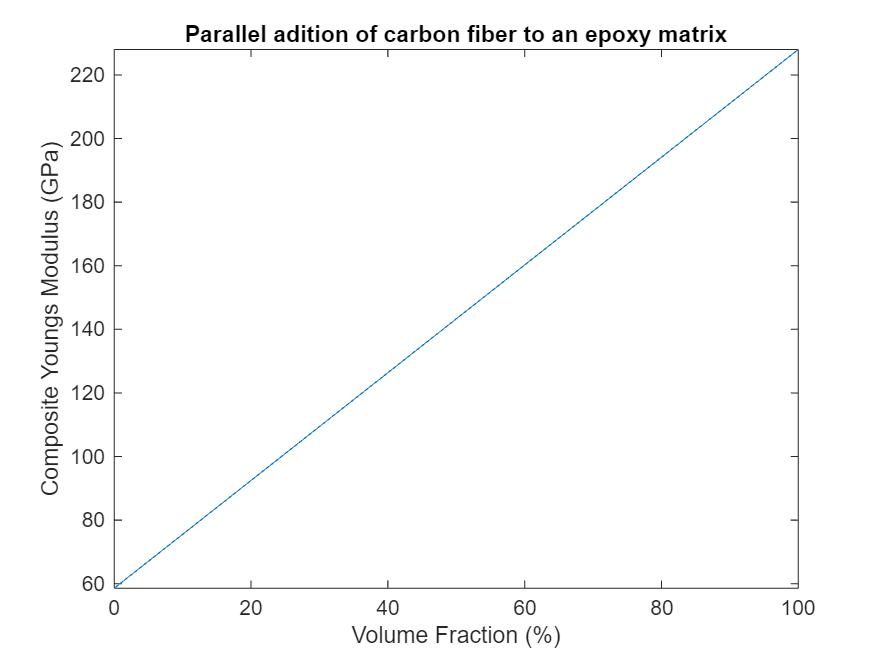



% parellel

eComp = @(vf) eFiber*(vf/100)+eEpoxy*(1-(vf/100));
fplot(eComp,[0,100])
xlabel('Volume Fraction (%)')
ylabel('Composite Youngs Modulus (GPa)')
title('Parallel adition of carbon fiber to an epoxy matrix')

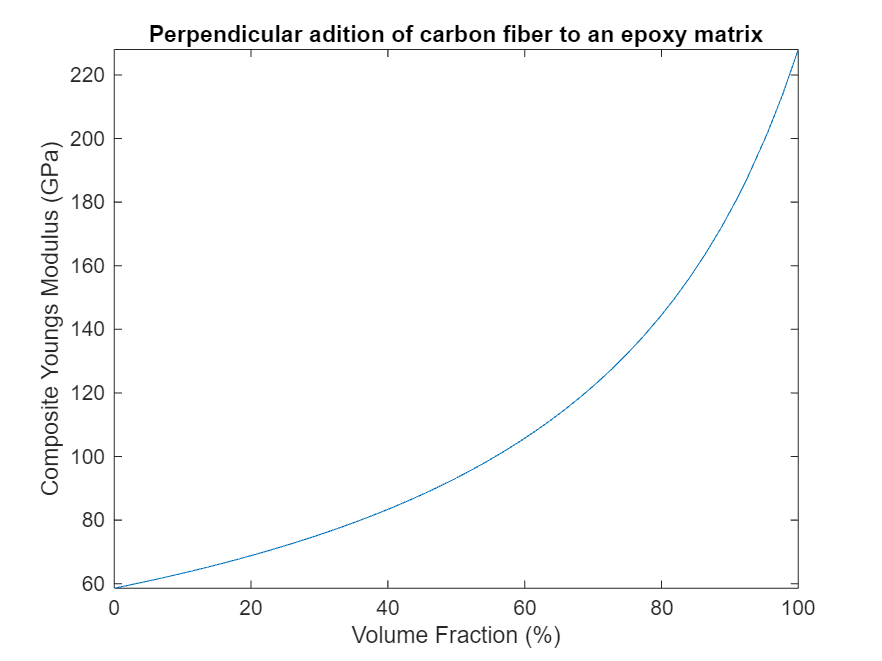

%perpendicular
eComp = @(vf) eEpoxy./(1+(vf./100).*(eEpoxy/eFiber-1));
fplot(eComp,[0,100]);
xlabel('Volume Fraction (%)')
ylabel('Composite Youngs Modulus (GPa)')
title('Perpendicular adition of carbon fiber to an epoxy matrix')